Part a, PDF and CDF of rayleigh random procss

% Parameters for the Rayleigh distribution
sigma = 1; % Scale parameter

% Range of x values
x = 0:0.01:10;

% Compute the probability density function (PDF)
pdf = raylpdf(x, sigma);

avg_R = mean(pdf);
var_R = var(pdf);
fprintf('Average of the Rayleigh sequence: %.4f\n', avg_R);

Average of the Rayleigh sequence: 0.0999


fprintf('Variance of the Rayleigh sequence: %.4f\n', var_R);

Variance of the Rayleigh sequence: 0.0343


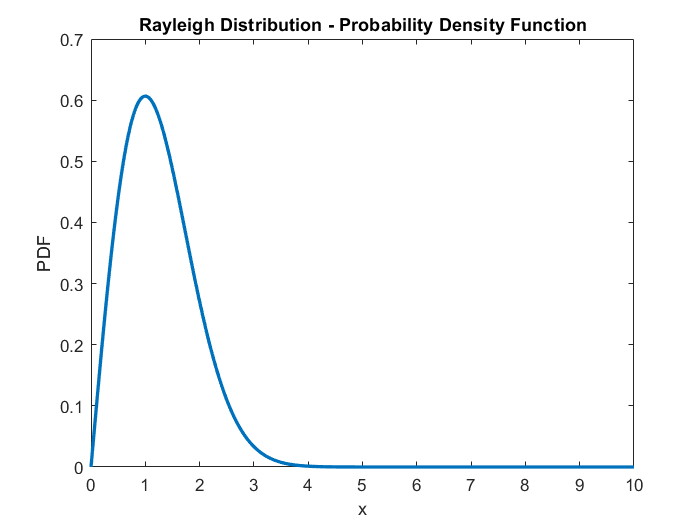



% Compute the cumulative distribution function (CDF)
cdf = raylcdf(x, sigma);

% Plot the PDF
figure;
plot(x, pdf, 'LineWidth', 2);
xlabel('x');
ylabel('PDF');
title('Rayleigh Distribution - Probability Density Function');

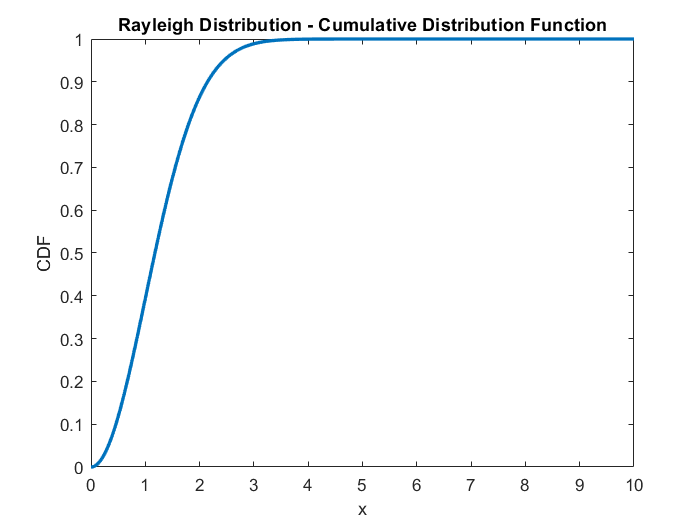


% Plot the CDF
figure;
plot(x, cdf, 'LineWidth', 2);
xlabel('x');
ylabel('CDF');
title('Rayleigh Distribution - Cumulative Distribution Function');

Part b, create two random variables and plot their histogram

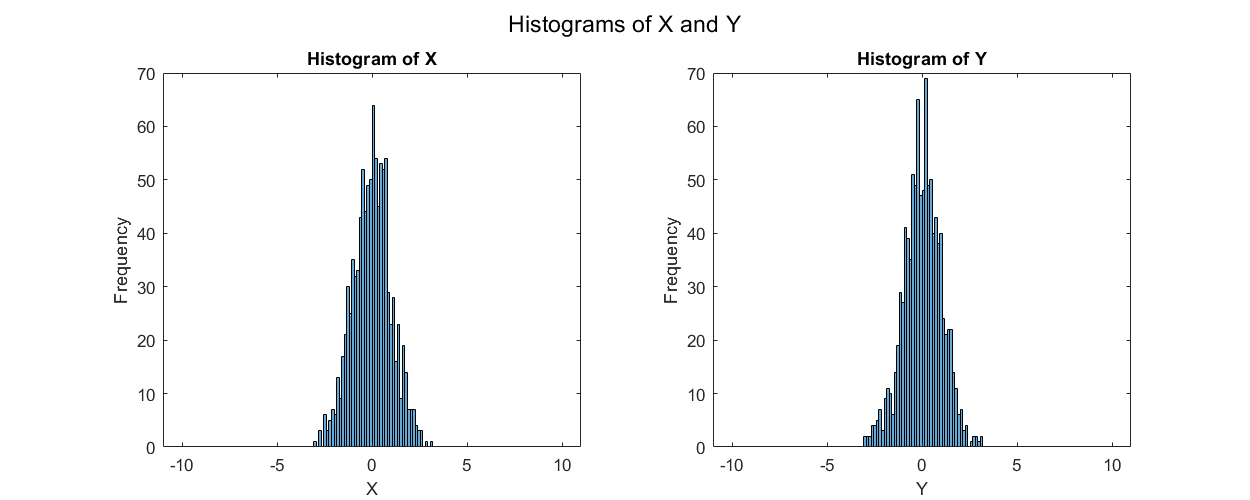



% Parameters for the normal random variables
mu = 0; % Mean
sigma = 1; % Standard deviation

% Generate the normal random variables X and Y
X = normrnd(mu, sigma, [1, 1000]);
Y = normrnd(mu, sigma, [1, 1000]);

% Plot the histograms of X and Y
figure;

% Histogram of X
subplot(1, 2, 1);
histogram(X, 'BinLimits', [-10, 10], 'NumBins', 150);
xlabel('X');
ylabel('Frequency');
title('Histogram of X');

% Histogram of Y
subplot(1, 2, 2);
histogram(Y, 'BinLimits', [-10, 10], 'NumBins', 150);
xlabel('Y');
ylabel('Frequency');
title('Histogram of Y');

% Adjust the figure layout
sgtitle('Histograms of X and Y');

% Optional: Set the figure size and position
set(gcf, 'Position', [100, 100, 1000, 400]);

Part c, create a rayleigh random process and plot its histogram

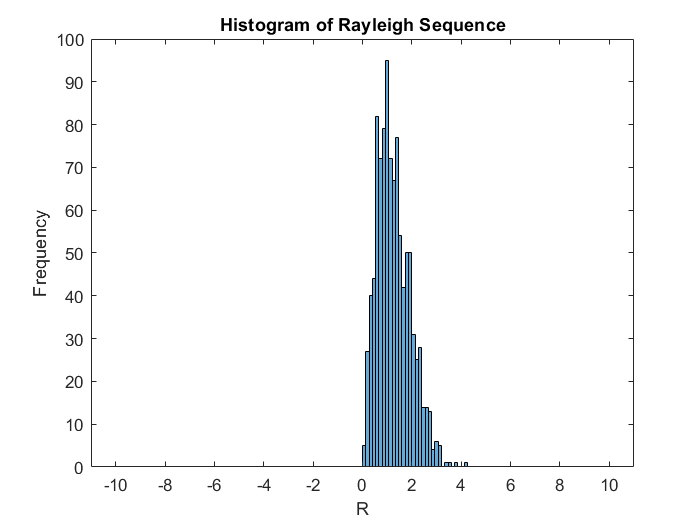


% Parameters for the normal random variables
mu = 0; % Mean
sigma = 1; % Standard deviation

% Generate the normal random variables X and Y
X = normrnd(mu, sigma, [1, 1000]);
Y = normrnd(mu, sigma, [1, 1000]);

% Compute the Rayleigh sequence
R = sqrt(X.^2 + Y.^2);

% Calculate the average and variance of the Rayleigh sequence
avg_R = mean(R);
var_R = var(R);

% Plot the histogram of the Rayleigh sequence
figure;
histogram(R, 'BinLimits', [-10, 10], 'NumBins', 150);
xlabel('R');
ylabel('Frequency');
title('Histogram of Rayleigh Sequence');


% Display the average and variance
fprintf('Average of the Rayleigh sequence: %.4f\n', avg_R);

Average of the Rayleigh sequence: 1.2687


fprintf('Variance of the Rayleigh sequence: %.4f\n', var_R);

Variance of the Rayleigh sequence: 0.4431


Part D, do two previous parts with different sequence length.

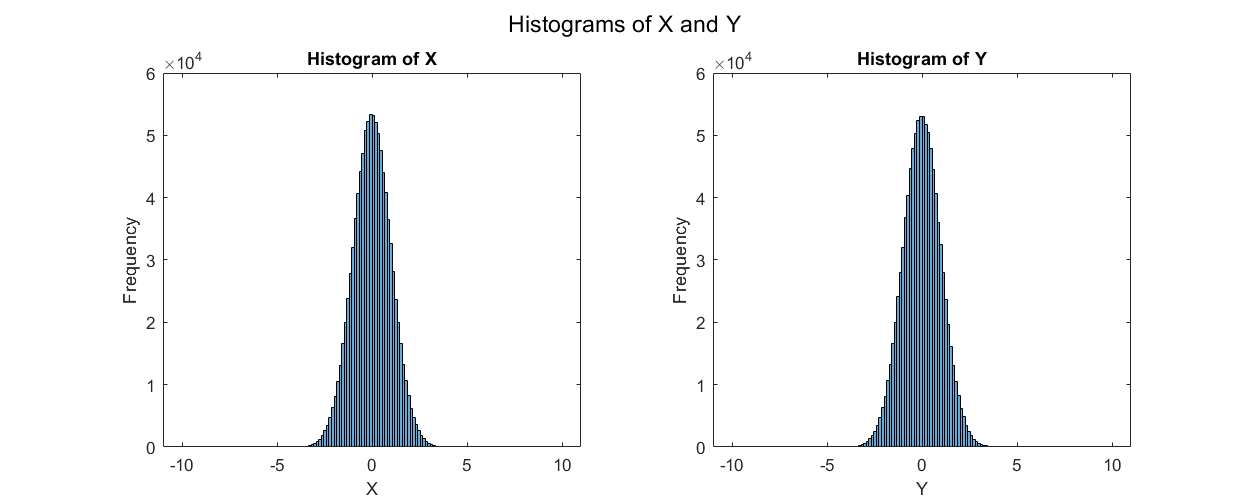



% Parameters for the normal random variables
mu = 0; % Mean
sigma = 1; % Standard deviation

% Generate the normal random variables X and Y
X = normrnd(mu, sigma, [1, 1000000]);
Y = normrnd(mu, sigma, [1, 1000000]);

% Plot the histograms of X and Y
figure;

% Histogram of X
subplot(1, 2, 1);
histogram(X, 'BinLimits', [-10, 10], 'NumBins', 150);
xlabel('X');
ylabel('Frequency');
title('Histogram of X');

% Histogram of Y
subplot(1, 2, 2);
histogram(Y, 'BinLimits', [-10, 10], 'NumBins', 150);
xlabel('Y');
ylabel('Frequency');
title('Histogram of Y');

% Adjust the figure layout
sgtitle('Histograms of X and Y');

% Optional: Set the figure size and position
set(gcf, 'Position', [100, 100, 1000, 400]);

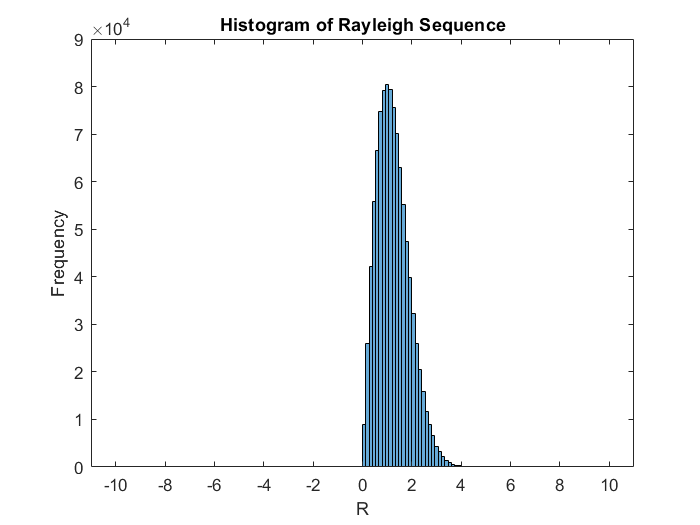





% Parameters for the normal random variables
mu = 0; % Mean
sigma = 1; % Standard deviation

% Generate the normal random variables X and Y
X = normrnd(mu, sigma, [1, 1000000]);
Y = normrnd(mu, sigma, [1, 1000000]);

% Compute the Rayleigh sequence
R = sqrt(X.^2 + Y.^2);

% Calculate the average and variance of the Rayleigh sequence
avg_R = mean(R);
var_R = var(R);

% Plot the histogram of the Rayleigh sequence
figure;
histogram(R, 'BinLimits', [-10, 10], 'NumBins', 150);
xlabel('R');
ylabel('Frequency');
title('Histogram of Rayleigh Sequence');


% Display the average and variance
fprintf('Average of the Rayleigh sequence: %.4f\n', avg_R);

Average of the Rayleigh sequence: 1.2532


fprintf('Variance of the Rayleigh sequence: %.4f\n', var_R);

Variance of the Rayleigh sequence: 0.4300
